# INTERPOLACJA

## RÓŻNE RODZAJE INTERPOLACJI

Sama definicja metody rozwiązania problemu interpolacji niewiele nam mówi o samej interpolacji:

***"W przedziale  [a,b] ****dane są punkty o współrzędnych oraz f(x_1 ),f(x_2 ), … f(x_N ). **Wyznaczyć taką funkcję ciągłą w przedziale [a,b], aby jej wykres przechodził przez wszystkie te punkty**.*

*Wyznaczenie takiej funkcji ciągłej f ̃(x,****p****), której wykres przechodzi przez zadane punkty {x_n,f(x_n)}, n=0,1,…,N"*

Zobaczmy zatem  na czym polega problem. Wykonamy kilka różnych interpolacji na tym samym zestawie punktów - wszystkie będą spełniały podaną powyżej definicję, ale ich efekty będą się różnić.

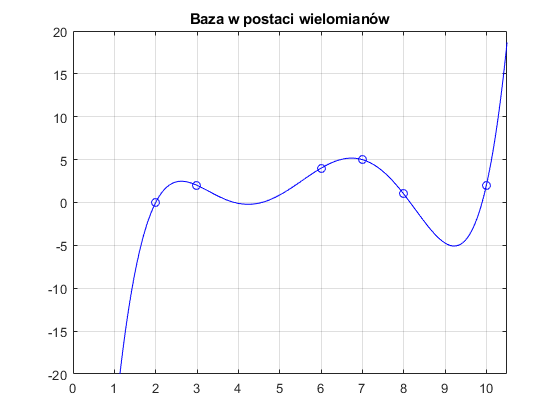

% Przypuśćmy, że nasz problem jest taki jak na slajdach
x=[2 3 6 7 8 10];
y=[0 2  4 5 1  2];

%Naszej funkcji oryginalnej nie znamy
xx=linspace(0,11,401);
% 1. Interpolacja wielomianowa
wsp=polyfit(x,y,numel(x)-1);
plot(x,y,'ob'); hold on;
plot(xx,polyval(wsp,xx),'bl');hold off;axis([0 10.5 -20 20]);grid on;
title("Baza w postaci wielomianów");

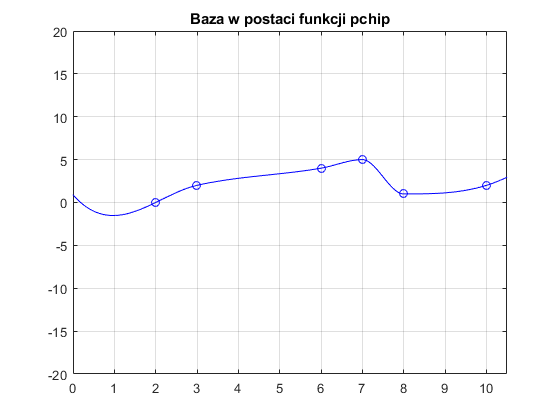


% 2. Inny rodzaj interpolacji
yy = interp1(x,y,xx,'pchip');figure();
plot(x,y,'ob'); hold on;
plot(xx,yy,'bl');hold off;axis([0 10.5 -20 20]);grid on;
title("Baza w postaci funkcji pchip");

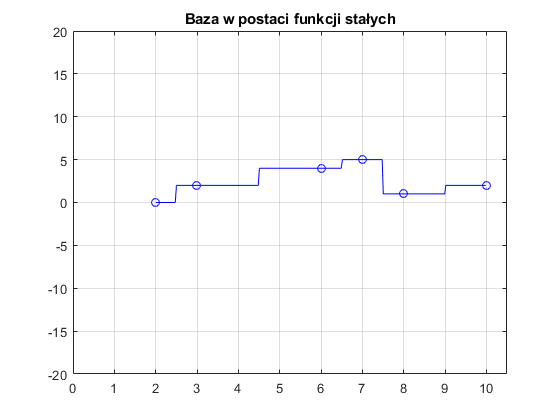


% 3. Inny rodzaj interpolacji
yy = interp1(x,y,xx,'nearest');figure();
plot(x,y,'ob'); hold on;
plot(xx,yy,'bl');hold off;axis([0 10.5 -20 20]);grid on;
title("Baza w postaci funkcji stałych");

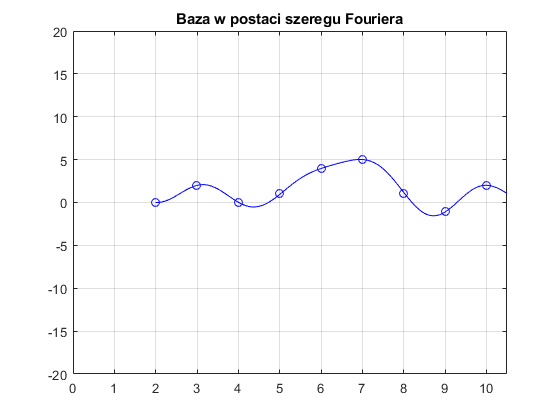


% 4. Inny rodzaj interpolacji
% UWAGA: interpft wymaga rownomiernie rozlozonych probek, dlatego tutaj
% (tylko w tej sekcji) podmieniamy dane na inny, rownomierny zestaw 9
% punktow zamiast wspolnego x=[2 3 6 7 8 10] uzywanego w pozostalych sekcjach.
x = 2:1:10;
y=[0 2 0 1 4 5 1 -1 2];
N=200;
yy = interpft(y,N);
x2 = linspace(2,11,N);

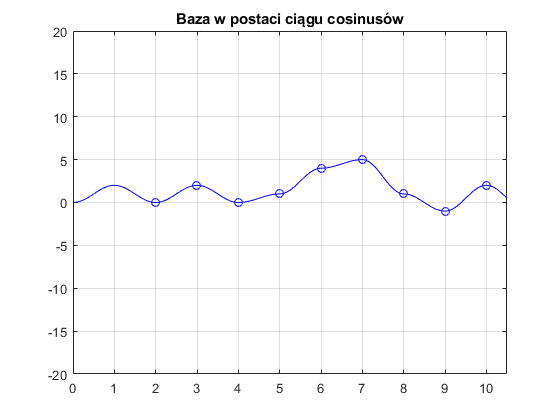

plot(x,y,'ob'); hold on;
plot(x2,yy,'bl');hold off;axis([0 10.5 -20 20]);grid on;
title("Baza w postaci szeregu Fouriera");

% 5. Inny rodzaj interpolacji
% Przywracamy oryginalny zestaw punktow (sekcja 4 go nadpisala powyzej)

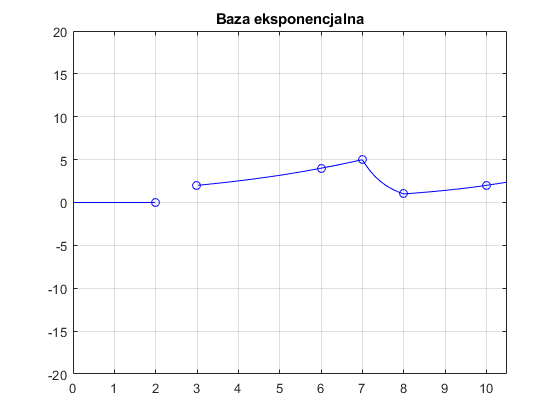

x=[2 3 6 7 8 10];
y=[0 2  4 5 1  2];
yy = cosint(x, y, xx);
plot(x,y,'ob'); hold on;
plot(xx,yy,'bl');hold off;axis([0 10.5 -20 20]);grid on;
title("Baza w postaci ciągu cosinusów");

% 6. Inny rodzaj interpolacji

x=[2 3 6 7 8 10];
y=[0 2  4 5 1  2];
yy = expint(x, y, xx);
plot(x,y,'ob'); hold on;
plot(xx,yy,'bl');hold off;axis([0 10.5 -20 20]);grid on;
title("Baza eksponencjalna");

% 7/ itd.itd.
% istnieje wiele rodzajów interpolacji nawet w dziedzinie jednego typu
% funkcji. Każda z nich jest wykorzystywana w jakimś zagadnieniu, gdzie ma
% najlepsze właściwości.

 

Wszystkie te interpolacje spełniają formalną definicję problemu interpolacji - wyznaczone funkcje przechodzą przez wszystkie punkty z danych wejściowych. Jednak jak widać różnią się one znacznie od siebie.

**Zasadniczym problemem interpolacji jest nie samo rozwiązanie matematyczne tego problemu, ale właściwy dobór rodzaju interpolacji do zakładanych celów.**

Zwróć uwagę również na fakt, że z definicji wynika ograniczenie wiarygodności interpolacji do przedziału [a,b], czyli w naszym przypadku do przedziału [2,10]. Wszystko co się dzieje poza tym przedziałem jest co do zasady niewiarygodne i z samego rozwiązania problemu interpolacji nie można wnioskować o właściwościach badanych funkcji poza tym przedziałem.

**WYKROZYSTYWANE FUNKCJE**

function yi = cosint(x, y, xi)

% COSINT 1-D piecewise cosine interpolation
%    COSINT(X,Y,XI) interpolates to find YI, the values of the underlying
%    function Y at the points in the array XI, using piecewise cosine
%    interpolation.  X and Y must be vectors of length N.

% Joe Henning - Fall 2011

n = length(x);

if n ~= length(y)
   fprintf('??? Bad input to cosint ==> X and Y must be of the same length\n');
   yi = [];
   return;
end

for i = 1:length(xi)
   % Find the right place in the table by means of a bisection.
   klo = 1;
   khi = n;
   while (khi-klo > 1)
      k = fix((khi+klo)/2.0);
      if (x(k) > xi(i))
         khi = k;
      else
         klo = k;
      end
   end
   
   h = x(khi) - x(klo);
   if (h == 0.0)
      fprintf('??? Bad input to cosint ==> X values must be distinct\n');
      yi(i) = NaN;
      continue;
   end
   
   % Evaluate cosine function
   cfact = (1 - cos(pi*(xi(i)-x(klo))/h))/2.0;
   yi(i) = y(klo) + cfact*(y(khi)-y(klo));
end
end

function yi = expint(x, y, xi)

% EXPINT 1-D piecewise exponential interpolation
%    EXPINT(X,Y,XI) interpolates to find YI, the values of the underlying
%    function Y at the points in the array XI, using piecewise exponential
%    interpolation.  X and Y must be vectors of length N.

% Joe Henning - Fall 2012

n = length(x);

if n ~= length(y)
   fprintf('??? Bad input to expint ==> X and Y must be of the same length\n');
   yi = [];
   return;
end

for i = 1:length(xi)
   % Find the right place in the table by means of a bisection.
   klo = 1;
   khi = n;
   while (khi-klo > 1)
      k = fix((khi+klo)/2.0);
      if (x(k) > xi(i))
         khi = k;
      else
         klo = k;
      end
   end
   
   h = x(khi) - x(klo);
   if (h == 0.0)
      fprintf('??? Bad input to expint ==> X values must be distinct\n');
      yi(i) = NaN;
      continue;
   end
   
   % Evaluate exponential
   yi(i) = y(klo)*(y(khi)/y(klo))^((xi(i)-x(klo))/h);
end
end